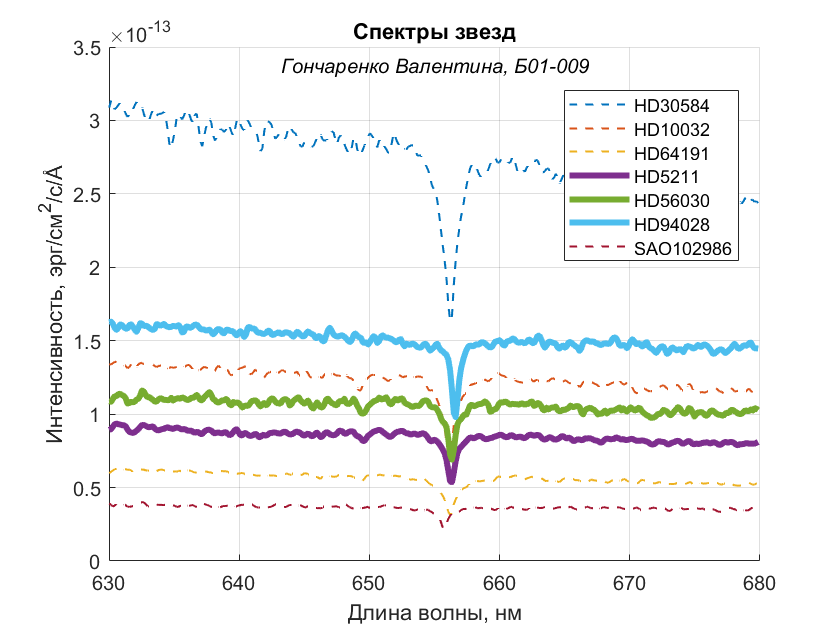

close all
clear variables
spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
starNames = importdata('star_names.csv');

lambdaPred = 656.28; %нм
speedOfLight = 299792.458; %км/с

nObsnabl = size(spectra, 1);
nObskol = size(spectra, 2);
lambdaEnd = lambdaStart + (nObsnabl - 1)*lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

minIntensity = ones(nObskol, 2);
for i = 1 : nObskol
    [minIntensity(i,1), minIntensity(i,2)] = min(spectra(:, i));
end

speed = ones(1, nObskol);
for i = 1 : nObskol
    speed(i) = speedOfLight * ((lambda(minIntensity(i,2))/lambdaPred) - 1);
end
speed = speed';

fg1 = figure;
hold on;
for i = 1:nObskol
    if speed(i) < 0
    plot(lambda, spectra(:, i), "LineStyle","--","LineWidth", 1);
    else
    plot(lambda, spectra(:, i), "LineStyle","-", "LineWidth", 3);
    end
    set(fg1, 'Visible', 'on');
    grid on;
end

text(643.2, (3.38*10^(-13)), 'Гончаренко Валентина, Б01-009', 'FontAngle', 'italic');
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
title({'Спектры звезд'});
legend(starNames,'Location',"best");

movaway = starNames(speed > 0);

saveas(fg1, 'спектры.png');